% Tensor Network B-splines two dimensional test
clear all

tt = 0:0.01:1;
[X,Y] = meshgrid(tt,tt);

coords = [X(:),Y(:)];

f = rastriginfcn(coords);

min(f)

ans = 0

max(f)

ans = 0.8050

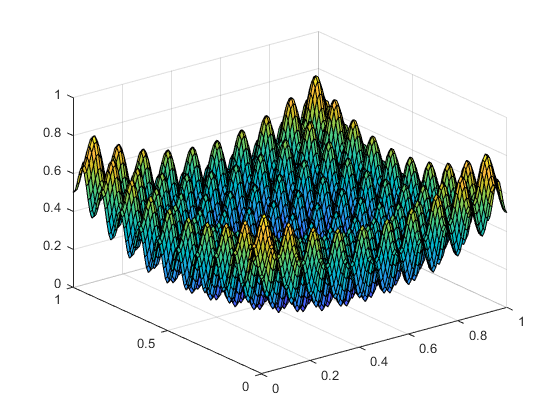


figure
surf(tt,tt,reshape(f,[length(tt) length(tt)]))


featurez = (rand(500,2))

featurez =     0.3389    0.8008
    0.5126    0.6173
    0.4234    0.4685
    0.3824    0.9316
    0.2149    0.8061
    0.0913    0.5059
    0.4239    0.0889
    0.6439    0.8866
    0.6222    0.7988
    0.8866    0.9836


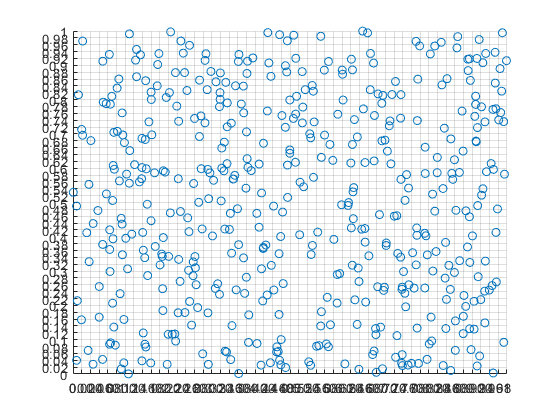

zeta = rastriginfcn(featurez);

scatter(featurez(:,1), featurez(:,2))

ticks = 0:1/50:1;
xticks(ticks);
yticks(ticks);
grid on

[N, d]=size(featurez); 

n = 2;                  %degree B-spline
m = 98;                  %Number of knot intervals
In = n+m;               %Number of B-splines

% Construct the basis vectors from the features
un = basisvectors(featurez,n,m);

maxrank = 3;
r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank));

[TN,Vm,Vp] = initTT(un,r,d);

lambda=1*10^-3;
tic
difforder=2;
MAXITR = 60;
[TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,[],lambda,difforder);
toc

Elapsed time is 0.559403 seconds.


trainerror = res1(end)

trainerror = 3.4900e-07

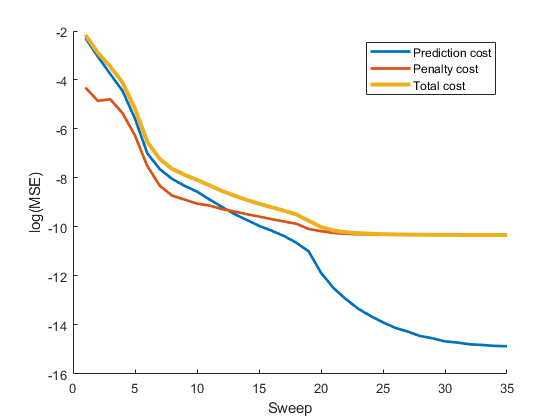


figure
hold on
plot(log(res1),'linewidth',2)
plot(log(res2),'linewidth',2)
plot(log(res1+res2),'linewidth',3)
hold off
legend('Prediction cost', 'Penalty cost', 'Total cost')
xlabel('Sweep')
ylabel('log(MSE)')


yhat = evalspline(TN,coords,n,m)

yhat =     0.3708
    0.4153
    0.4740
    0.5410
    0.5827
    0.5754
    0.5420
    0.5011
    0.4521
    0.4090


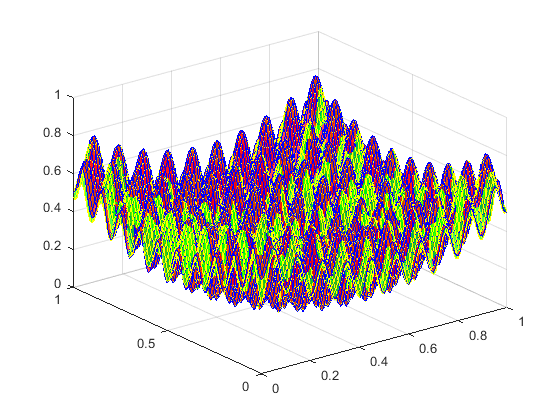


figure
surf(tt,tt,reshape(f,[length(tt) length(tt)]), 'FaceColor','r', 'FaceAlpha',0.7, 'EdgeColor','b')
hold on
surf(tt,tt,reshape(yhat,[length(tt) length(tt)]), 'FaceColor','g', 'FaceAlpha',0.7, 'EdgeColor','y')
hold off

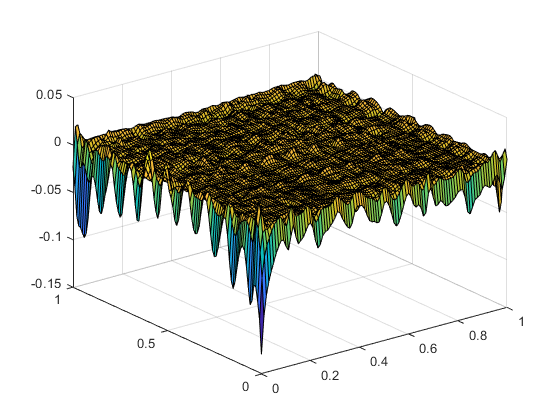


surf(tt,tt,reshape(yhat-f,[length(tt) length(tt)]))


RMSE = sqrt(immse(f,yhat)/norm(f))

RMSE = 9.7009e-04


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %Degrees of freedom/ TT storage size.
disp(['Compression: ' num2str(dof/Pcount)])  %ratio

Compression: 0.06



AA = rand(50000,10000)

AA =     0.3125    0.3126    0.6639    0.1316    0.9176    0.4529    0.1828    0.4324    0.9013    0.0773    0.0151    0.2905    0.4047    0.8970    0.8191    0.6892    0.6799    0.1970    0.4741    0.3748    0.7962    0.8979    0.7187    0.2642    0.7638    0.1017    0.9687    0.6270    0.4764    0.3683    0.3351    0.8001    0.8245    0.8530    0.6582    0.4350    0.8621    0.1468    0.9407    0.5906    0.2858    0.4870    0.5784    0.1793    0.9923    0.4102    0.4941    0.3017    0.8371    0.5829
    0.1885    0.7064    0.6011    0.1369    0.5715    0.5695    0.5632    0.7943    0.9297    0.0943    0.6941    0.8799    0.5115    0.1177    0.8578    0.1550    0.5654    0.2742    0.3391    0.8206    0.2782    0.5444    0.4661    0.5607    0.1332    0.2331    0.6697    0.8431    0.5828    0.9358    0.0708    0.8605    0.4374    0.2390    0.6096    0.2159    0.0335    0.7692    0.9195    0.1674    0.0251    0.6609    0.6067    0.8689    0.5527    0.8807    0.4241    0.9746    0.6292    

BB = rand(10000,1)

BB =     0.4636
    0.7845
    0.3852
    0.5366
    0.5660
    0.9822
    0.2060
    0.6857
    0.8821
    0.2252


CC = AA*BB

CC = 	1.0e+03 *

    2.5264
    2.4922
    2.4941
    2.5098
    2.5115
    2.5102
    2.5424
    2.5480
    2.5348
    2.5176


pinv(AA)*CC

ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
